clear
m1=3; %massa corpo 1
m2=4; %massa carrello 2
m3=2; %massa carrello 3
m=0.2; %massa pulegga
k1=0.5; %0.5;
k2=0.5;
k3=0.5;
b2=0.4;
b3=0.4;
rm=0.2;
M=(m2+0.5*m); %M=1/(m2+0.5*m);
a=20;
g=9.81;

A=[0       1    0                  0        0    0
    -k1/m1 0  k1/m1                0        0    0
    0      0    0                  1        0    0
    k1/M   0  -(k1+k2+k3)/M   -(b2+b3)/M  k3/M  b3/M
    0      0    0                  0        0    1
    0      0    k3/m3           b3/m3    -k3/m3 -b3/m3];
B=[0            0       0
  sin(a)   sin(a)/m1    0
    0           0       0
    0           0       0
    0           0       0
    0           0       1];
C=[1 0 0 0 0 0
   0 0 1 0 0 0
   0 0 0 0 1 0];
D=[0 0 0; 0 0 0;0 0 0];

sys=ss(A,B,C,D);
eig(sys)

ans =   -0.1465 + 0.6992i
  -0.1465 - 0.6992i
  -0.0347 + 0.4599i
  -0.0347 - 0.4599i
  -0.0164 + 0.2157i
  -0.0164 - 0.2157i


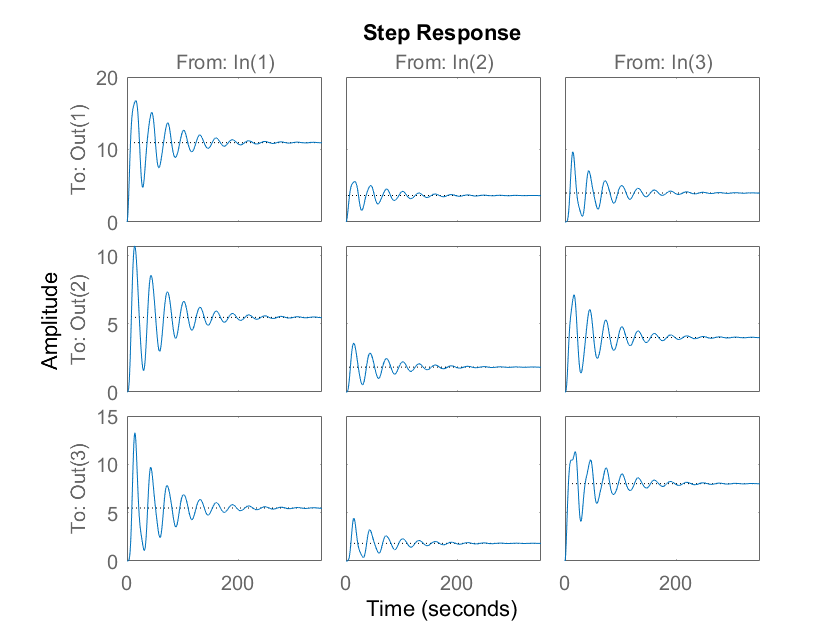

%risposte del sistema in funzione di un gradino applicato rispettivamente
%al primo,secondo e terzo ingresso
step(sys);

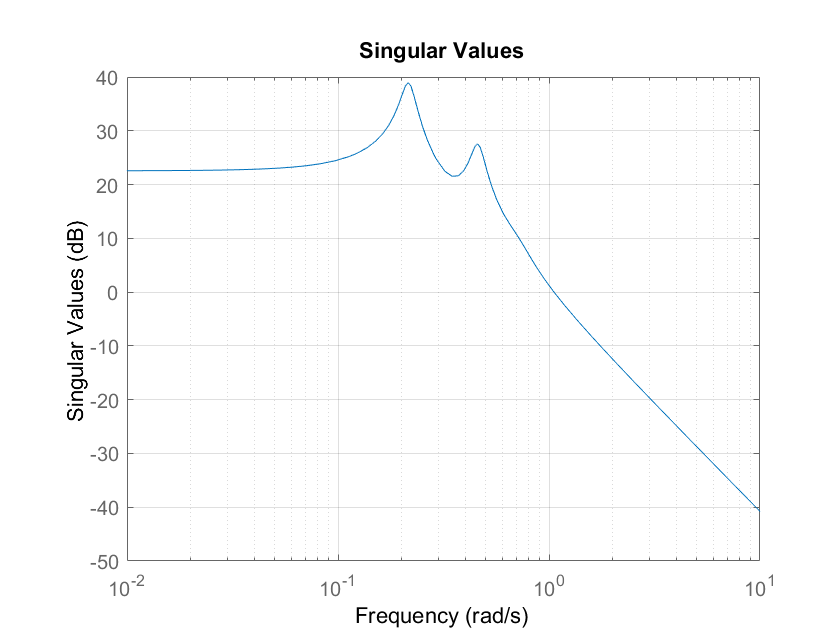

%siccome il terzo ingresso NON è un ingresso di controllo conviene vedere i
%sigma plot separatamente
%un solo sigma plot relativo a ogni ingresso
%tramite i sigma plot posso valutare la norma Hinfinito vista dai segnali
%di ingresso 
%Il valore della Y è 26.3db

figure
sigma(sys(:,1))

grid

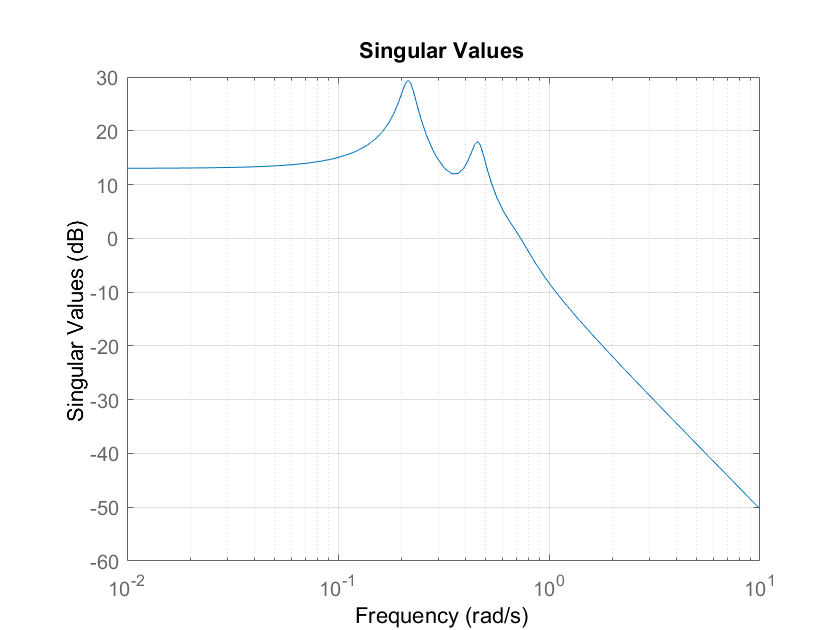


figure
sigma(sys(:,2))  %%Il valore della Y è 28db

grid

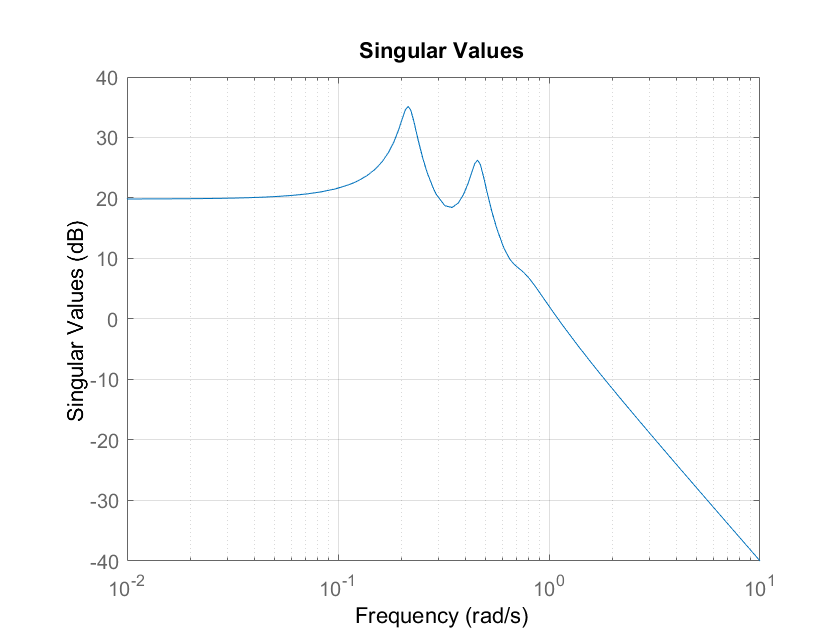

figure
sigma(sys(:,3)) %sigma plot relativo al disturbo
%Il valore della Y è 28db
grid

%valore esatto delle tre norme Hinfinito
hinfnorm(sys(:,1)) %norma Hinf vista dall'ingresso di controllo

ans = 88.5547

hinfnorm(sys(:,2))

ans = 29.5182

hinfnorm(sys(:,3)) %norma Hinf vista dall'ingresso di disturbo

ans = 57.2446

%norma Hinf complessiva del sistema
%posso vederla come una m.d.t. che ha 1 riga e 3 colonne, quando metto in
%colonna i tre sistemi la norma Hinf è sempre più grande del più grande
%delle norme
hinfnorm(sys)

ans = 109.3412

%Procediamo alla progettazione del controllore (l'obbietttivo è insegire
%dei riferimenti, per esempio gradino o riferimenti sinusoidali)
%Dovendo inseguire un riferimento a gradino una possibilità è quella di
%inserire un integratore
%SISTEMA AUMENTATO

Aaug=[A zeros(6,2);
     -C(1,:)  0 0;
     -C(2,:)  0 0];
Baug=[B; zeros(2,3)]; %sel sist aumentato considero sempre solo gli ultimi due ingressi (quelli di controllo)
Caug=[C zeros(3,2)];  %aggiungo due righe perchè agg 2 integ le variabili di stato sono aumentate di 2
Daug=D;

%devo verificare che l'aggiunta dell'integratore non mi faccia perdere le
%proprietà strutturali dell'impianto (siccome progetteremo controllore
%basato sulla legge di retazione dello stato quello che devo fare è
%verificare che il sistema rimanga completamente controllabile)
%NOTA:non ci interessa la controllabilità considerando i tre ingressi ma
%solo i primi due (che sono quelli che uso per progettare il controllore)
%quindi tramite la matrice ctrb scrivo la matrice di controll. solo
%relativiva ai primi due ingressi
sysAug=ss(Aaug,Baug,Caug,Daug);
%Rango matrice di controllabilità sistema aumentato
rank(ctrb(Aaug,Baug(:,2:3))) %considero solo gli ultimi due ingressi (considero solo le ultime due colonne)

ans = 8

%Imposto il problema come un problema di controllo ottimo LQ (il cui
%obbiettivo è contrastare semplicemente una condizione iniziale -> contrastiamo l'effetto delle condizioni iniziali)
%Quindi in questo progetto il riferimento non entra (ovviamente nel momento
%in cui è stato messo l'integratore e faccio entrare r-y se il sys a ciclo
%chiuso è a.s. l'errore di inseguimento andrà automaticamente a 0)
%Non mi curo neanche della presenza del disturbo
%(ricordo espressione funzione obbiettivo, siccome sono interessata a
%controllare la posizione dei due carrelli a x^T*u*x andiamo a sostituire
%y^T*Qtilde*Y


r1=1;
r2=1;
r3=1;
Q=r1*(Caug'*Caug)+r2*blkdiag(zeros(6),1,1); %il secondo (matrice diagonale a blocchi termine mi aggiunge un 1 alla Q nella posizione e (7,7)e(8,8) per gli integratori
%se considerassi solo questo secondo termine come matrice di peso peserei
%solo l'azione integrale
%Combinando le due matrici di peso, ottengo una matrice di peso in cui
%valuto la posizione del corpo m1 e del primo carrello e la variabile di stato dell'integratore
R=r3 * diag([Baug(2,2) Baug(6,3)]); %tramite R peso gli ingressi di controllo
%Tramite comando lqr calcolo matrice di retroazione dello stato
[K,P,e]=lqr(sysAug(:,2:3),Q,R); %ci restituisce K, sol eq. algebrica di riccati e autovalori sistema a ciclo chiuso
K %coefficienti che devo usare per retrazionale le mie (8?)variabili di stato

K =     4.4175    5.3764    1.2709    2.0206    0.1343    0.1962   -1.7759   -0.3638
    0.3278    0.1962    1.4771    4.2474    1.0577    1.5241    0.2007   -0.9797


%P deve risultare definita positiva
P

P =     6.1658    4.4175    1.7994    3.2233    0.2298    0.3278   -2.8662   -0.7874
    4.4175    5.3764    1.2709    2.0206    0.1343    0.1962   -1.7759   -0.3638
    1.7994    1.2709   12.2374   16.4183    1.1813    1.4771    0.0242   -6.2623
    3.2233    2.0206   16.4183   39.0841    2.6772    4.2474    1.5571  -10.6266
    0.2298    0.1343    1.1813    2.6772    1.4333    1.0577    0.0881   -0.6740
    0.3278    0.1962    1.4771    4.2474    1.0577    1.5241    0.2007   -0.9797
   -2.8662   -1.7759    0.0242    1.5571    0.0881    0.2007    2.8074   -0.4251
   -0.7874   -0.3638   -6.2623  -10.6266   -0.6740   -0.9797   -0.4251    5.1700


%P deve risultare definita positiva(verifica fatta dal prof in C.W.)
eig(P)

ans =     0.3680
    0.6678
    1.4136
    1.8700
    1.9548
    4.9616
   11.2144
   51.3483


%Ho due poli (reali) dovuti alle azioni integrali
e

e =   -0.2347 + 0.6632i
  -0.2347 - 0.6632i
  -0.2517 + 0.0000i
  -0.4471 + 0.7680i
  -0.4471 - 0.7680i
  -0.6302 + 0.7805i
  -0.6302 - 0.7805i
  -0.6796 + 0.0000i


%Ho un tempo di assestamneto alto(circa 30/35 sec vedi scope posizioni) 
%Vediamo come ridurre il tempo di assestamento
%Lo posso fare andando a cambiare il rapporto tra la matrice Q e la matrice
%R (in quanto fa da trade off tra l'ampiezza dell'azione di controllo e la
%velocità con cui le variabili di stato in evoluzione libera(ricorda condizioni iniziali nulle) vengono
%portate a zero)
%aumento peso sulla Q o diminuisco peso sulla R
r1=50; %aumento peso sulle uscite y (sembra diminuire sov.)
r2=200; %peso sulle azioni integrali -> conviene aumentare per velocizzare risposta (1->10 il t.a. si dimezza.) (Aumentandolo sembra diminuisca la sovraelongazione, se aumento troppo la posizione del carrello diverge)
r3=0.25; %(sembra diminuire sov.)
Q=r1*(Caug'*Caug)+r2*blkdiag(zeros(6),1,1);
%Q(3,3)=Q(3,3)*10; %peso di più lo spostamento del carrello 
%Q(1,1)=Q(1,1)*100; %peso di più lo spostamento della massa m1
R=r3 * diag([ Baug(2,2) Baug(6,3)]);
[K,P,e]=lqr(sysAug(:,2:3),Q,R);
K

K =    50.1469   18.1489   20.3495   21.2339   -0.6574    0.2407  -50.4563   -9.1113
    1.3668    0.2407   47.5103   73.0823   11.0552    5.8326    5.0262  -27.8341


P

P = 	1.0e+03 *

    0.0568    0.0125    0.0298    0.0297   -0.0009    0.0003   -0.0694   -0.0143
    0.0125    0.0045    0.0051    0.0053   -0.0002    0.0001   -0.0126   -0.0023
    0.0298    0.0051    1.1131    1.0330   -0.0294    0.0119    0.0368   -0.6470
    0.0297    0.0053    1.0330    1.8033   -0.0739    0.0183    0.1372   -0.6413
   -0.0009   -0.0002   -0.0294   -0.0739    0.0220    0.0028   -0.0067    0.0204
    0.0003    0.0001    0.0119    0.0183    0.0028    0.0015    0.0013   -0.0070
   -0.0694   -0.0126    0.0368    0.1372   -0.0067    0.0013    0.2096   -0.0336
   -0.0143   -0.0023   -0.6470   -0.6413    0.0204   -0.0070   -0.0336    0.5772


e

e =   -0.2849 + 0.7133i
  -0.2849 - 0.7133i
  -0.4134 + 0.0000i
  -1.8255 + 0.0000i
  -1.8322 + 2.2781i
  -1.8322 - 2.2781i
  -2.6388 + 2.6792i
  -2.6388 - 2.6792i


%La tecnica di controllo ottimo LQ (attraverso la sua finzione obbiettivo)
%fornisce la legge di controllo ottimo che ci consente di andare ad
%abbattere certe condizioni iniziali. Noi in realtà la usuamo in modo
%"improprio" perche la usuamo per andare a fare l'inseguimento di un
%gradino.
%Tramite le matrici Q e R possiamo andare a soddisfare tutte le specifiche

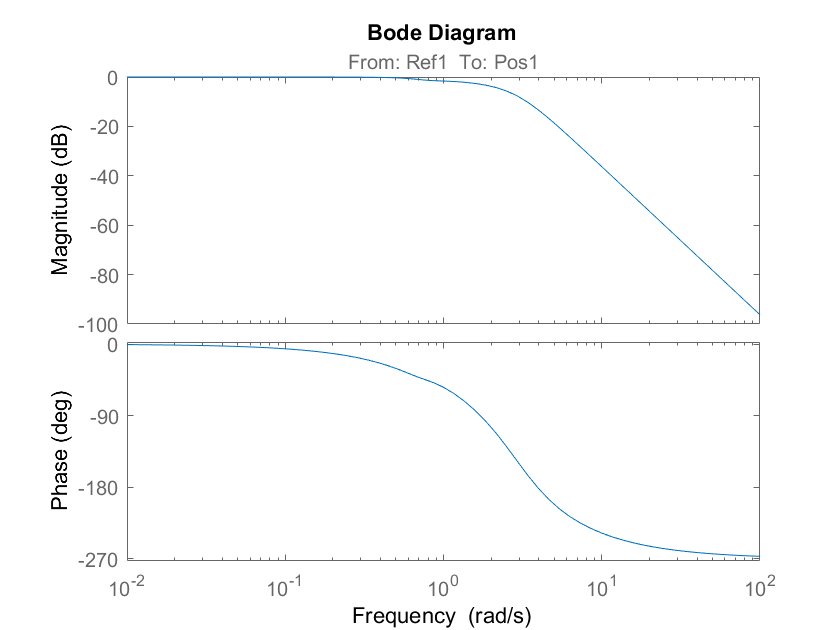

%CONTROLLO H INFINITO
%Per poter paragonare i due controllori conviene andarsi a costruire il
%sistema a ciclo chiuso
%(ottenuto dalla mia legge di retroazione dello stato)
%(sist. ciclo chiuso LQ?)
ClLQ=closedLoop(A,B,eye(6),zeros(6,3),K); %Passo le matrici A,B,C e D del modello simulink e il K
%ClLQG=closedLoopLQG(A,B,eye(6),zeros(6,3),K);
%Ci da le funzioni di trasferimento a ciclo chiuso

%Guardo la funzione di trasferimento tra rif1 e pos1
%mi aspetterò (siccome c'è un'azione integrale) un sist. con guadagno
%statico pari a 1
bode(ClLQ(1,1))

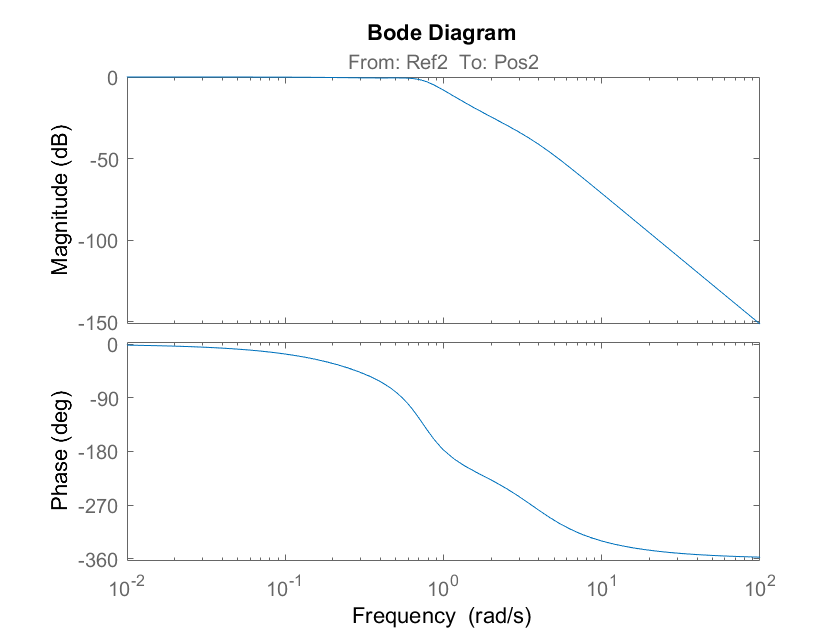

%ottengo un sistema (con Gs=1) passa basso con banda passante (banda a
%-3db)->1rad/s
%Ciò ci dice anche che ho progettato andando a guardare la risposta a
%gradino posso andare a inseguire anche delle sinusoidi fino alla
%frequenza(pulsazione)
%di circa 1rad/S. Se volessi andare oltre 1rad/s dovrei aumentare la banda
%passante del sistema a ciclo chiuso (devo tornare in progettazione e
%accettare che le ampiezze di controllo diventino più grandi)

%Guardo la funzione di trasferimento tra rif2 e pos2
bode(ClLQ(2,2))

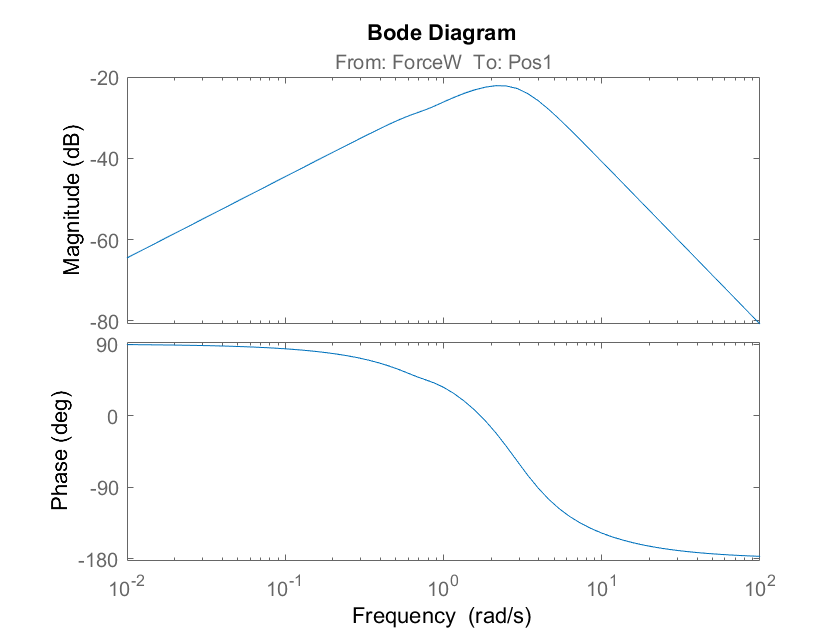

%posso andare a vedere l'effetto del disturbo sulla mia variabile
%controllata
%siccome ho integratore nell'origine(e quindi reiettiamo perfettamente un disturbo costante) 
% la f.d.t da disturbo a variabile controllata è di tipo passa banda
bode(ClLQ(1,3))

%bode(ClLQ(2,3)) non credo mi serva tanto il disturbo agisce solo su m1



%open loop
olLQ=openLoop(A,B,eye(6),zeros(6,3),K);

%vediamo i margini di stabilità 
%il controllore LQ deve avere un margine di guadagno che va da 0.5 a +inf e uno di fase
%di circa +-60 gradi (-120 al prof va bene)
%margin(olLQ); %solo per sist SISO

CONTROLLO OTTIMO H INFINITO

%Nel CONTROLLO OTTIMO H INFINITO riesco a portare in conto l'effetto del disturbo
%Fattore che mi pesa l'azione integrale mentre gli 0 sono i coefficienti
%che moltiplicano le variabili di stato
factor=5;
%NOTA: nel controllo LQ per pesare agivo sulla matrice Q qui invece agisco
%sulla matrice C
Caug1=[Caug;0 0 0 0 0 0 factor 0;0 0 0 0 0 0 0 factor];
Caug1(2,3)=Caug1(2,3)*2; %dim sovraelong sul secondo segnale(carrello) 

%Ovviamente se aumento il numero ri righe di C devo aumentare anche il
%numero delle righe di D
Daug1=[Daug;0 0.5 0;0 0 1]; %con 0.05 e 1 sto pesando l'azione di controllo
%peso sugli integ cambiato perchè altrimenti avrvo controllo troppo ampio
%se 0.05->1 ho un miglior ingresso di controllo ma con o.o5 ho un andamento più simile a quello di LQ (dello stato) 
sysAug1=ss(Aaug,Baug,Caug1,Daug1);
%Il comando hinffi assume che le ultime ncont colonne siano quelle relative
%all'azione di controllo (PER QUESTO NEL MODELLO COME U1 HO SCELTO IL
%DISTURBO) 
% Per risolvere prog. ottimo H inf. devo risolvere eq. di riccati che
% dipende da gamma. in hinffi viene implementata la ricerca binaria e viene
% abbassato il valore di gamma il più possibile
[Kinf,CL,gamma] = hinffi(sysAug1,2) %gli devo passare il sist. e il numero delle variabili di controllo

Kinf = 	1.0e+03 *

   -3.0512   -2.1604   -0.2015   -0.0991   -0.0041   -0.0037    4.6478   -0.0111         0
   -0.0047   -0.0031   -0.0094   -0.0132   -0.0015   -0.0022    0.0055    0.0050         0


CL =
 
  A = 
            x1       x2       x3       x4       x5       x6       x7       x8
   x1        0        1        0        0        0        0        0        0
   x2   -928.7   -657.5   -61.16   -30.17   -1.246    -1.14     1414   -3.376
   x3        0        0        0        1        0        0        0        0
   x4    0.122        0  -0.3659  -0.1951    0.122  0.09756        0        0
   x5        0        0        0        0        0        1        0        0
   x6   -4.662   -3.077   -9.162   -12.98   -1.761    -2.37    5.547    4.987
   x7       -1        0        0        0        0        0        0        0
   x8        0        0       -1        0        0        0        0        0
 
  B = 
           u1
   x1       0
   x2  0.9129
   x3       0
   x4       0
   x5       0
   x6       0
   x7       0
   x8       0
 
  C = 
           x1      x2      x3      x4      x5      x6      x7      x8
   y1       1       0       0       0       0       0       0       0


gamma = 1.5032

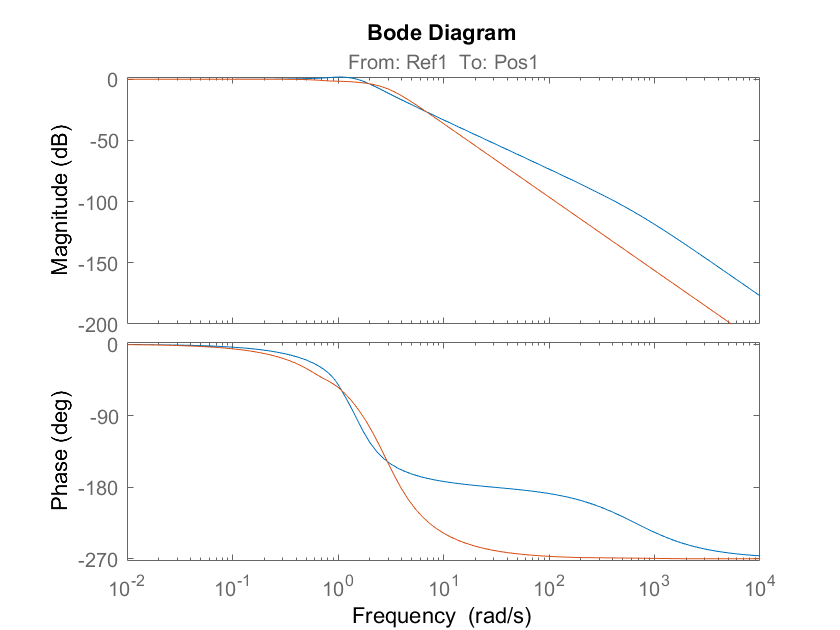

%NOTA: l'ultima colonna di Kinf è (nel prog. Full informetion l'ngretto u
%misura lo stato ma anche il disturbo quindi la legge di controllo è k1*x+K2*w)
%noi abbiamo coeff =0 quindi è retrazione di stato comunque
%Siccome voglio usare lo stesso schema di simulazione che ho usatp per
%controllo LQ devo portare in conto che li il K lo si assume con retrazione
%negativa nell'Hinf il K va inteso con retrazione POSITIVA
%QUINDI cambio di segno al K
Kinf=-Kinf;

%Calcolo sist. a ciclo chiuso
ClHinf=closedLoop(A,B,eye(6),zeros(6,3),Kinf);
bode(ClHinf(1,1),ClLQ(1,1)); %qanda passante di LQ più ampia(?)

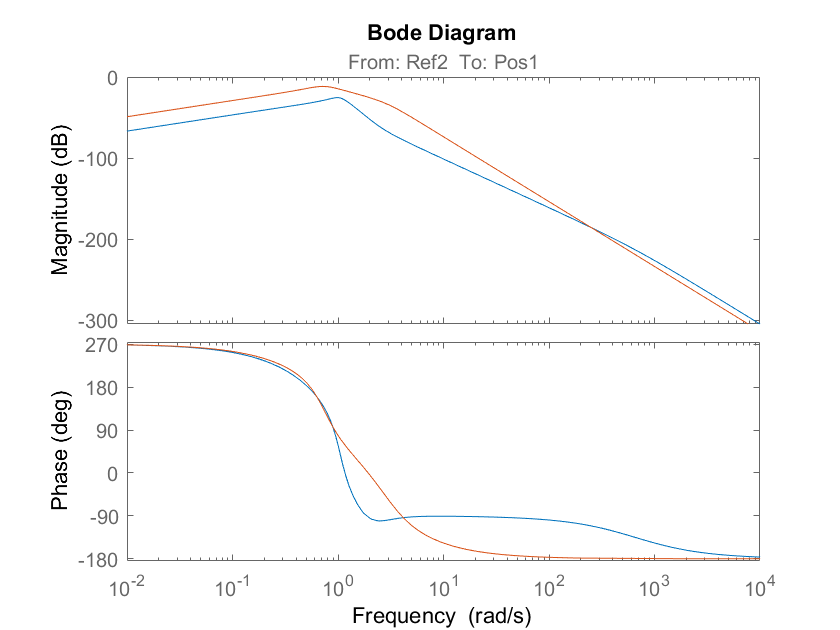

figure
bode(ClHinf(1,2),ClLQ(1,2));

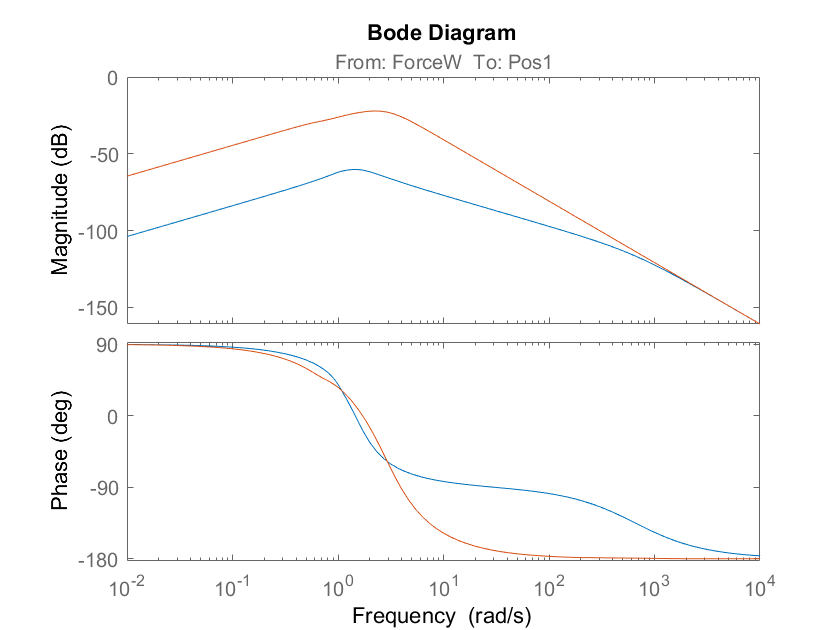

figure %reiezione al disturbo %guadagno più basso-> miglior reiezione del disturbo
bode(ClHinf(1,3),ClLQ(1,3)); % Hinf più bassa perchè noi effettivamnete teniamo conto della presenza del disturbo

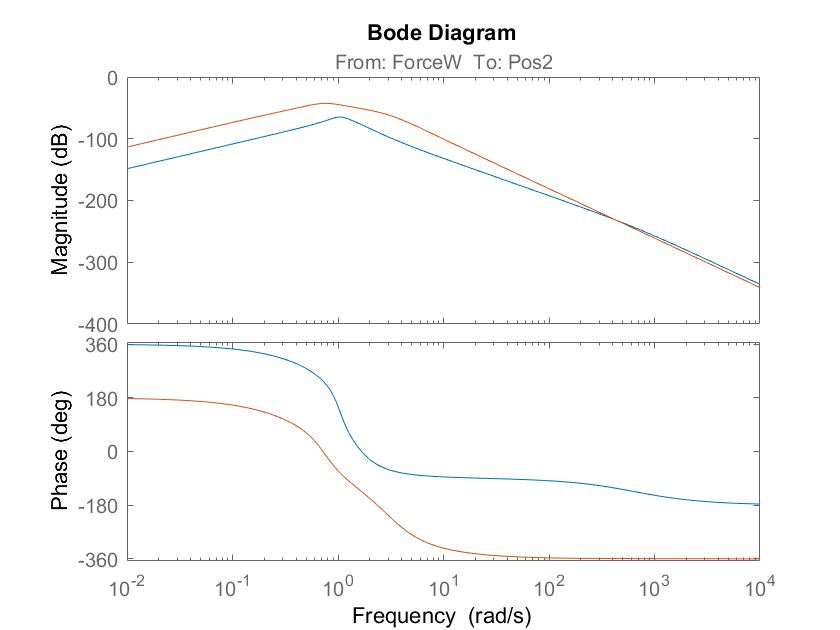

figure
bode(ClHinf(2,3),ClLQ(2,3));

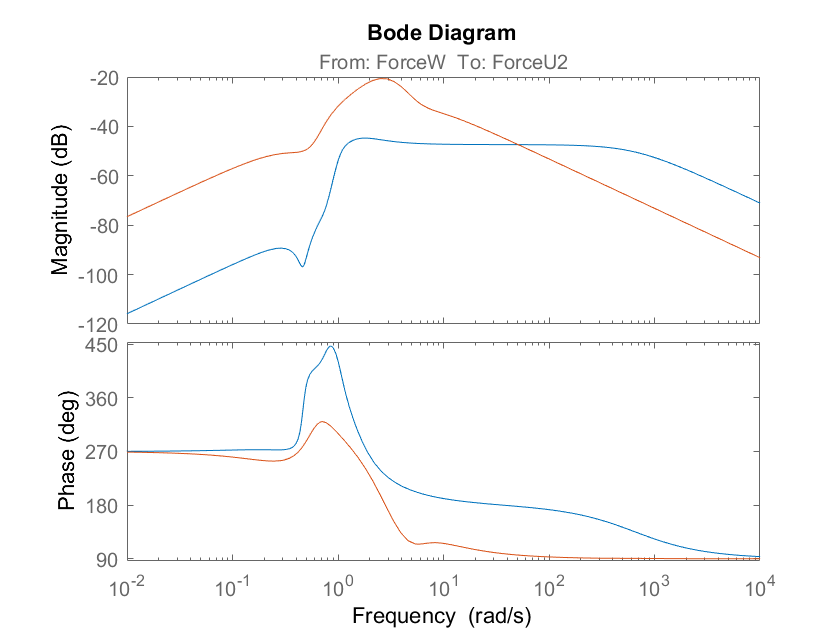

figure
bode(ClHinf(end,3),ClLQ(end,3)); %nel controllore Hinf il picco in frequenza è più basso però la legge di controllo si estende su una banda di freq. molto più ampia.Per questo l'azione di controllo in Hinf è più rapida (vero nel mio caso?)

%Potrei cercare di migliorare il controllore Hinf per fargli reiettare
%meglio il disturbo -> aumentare peso azione integrale-> fattore 2->10


Closed loop system

function clLoop=closedLoop(A,B,C,D,K)
G=ss(A,B,C,D);
%per questo sistema(quello in simulink) posso definire dei nomi per gli ingressi e per le
%uscite
G.InputName={'ForceW','ForceU1','ForceU2'}; %primo ingresso di disturbo e il secondo l'ingresso di controllo
G.OutputName={'Pos1','Vel1','Pos2','Vel2','Pos3','Vel3'};

%Guadagno integrale
Ki1=K(1,7); %primo integratore che agisce sulla prima massa
Ki2=K(2,8); %secondo integratore che agisce sulla seconda massa
%Definisco un sistema che fa da integratore
sysItg1=ss(0,1,Ki1,0);
sysItg1.InputName='errorPos1';
sysItg1.OutputName='IntegralAction1';
%Definisco un sistema che fa da integratore
sysItg2=ss(0,1,Ki2,0);
sysItg2.InputName='errorPos2';
sysItg2.OutputName='IntegralAction2';

%Prendo la matrice di retroazione dello stato dell'impianto
Kf=K(:,1:6);
%Tale sist. non ha variabili di stato perchè è un sist. algebrico
StFeedMatrix=ss([],[],[],Kf); %realizza la relazione Ingresso-uscita y=Kf*u
StFeedMatrix.InputName={'Pos1','Vel1','Pos2','Vel2','Pos3','Vel3'};
StFeedMatrix.OutputName={'StateFeedbackAction1','StateFeedbackAction2'}; %è la parte di retrazione che riguarda l'azione con retroazione di stato


Sum1=sumblk('errorPos1=Ref1-Pos1');
Sum2=sumblk('errorPos2=Ref2-Pos2');
Sum3=sumblk('ForceU1=-IntegralAction1-StateFeedbackAction1');
Sum4=sumblk('ForceU2=-IntegralAction2-StateFeedbackAction2');
%ottengo il sistema a ciclo chiuso tramite il comando connect(gli passo
%tutti i sistemi che mi servono a definire il sist. a ciclo chiuso e gli
%dico quale sono le etichette degli ingressi e delle uscite
clLoop=connect(G,sysItg1,sysItg2,StFeedMatrix,Sum1,Sum2,Sum3,Sum4,{'Ref1','Ref2','ForceW'},{'Pos1','Pos2','Pos3','Vel1','Vel2','Vel3','ForceU1','ForceU2'});
end

%open loop system
function olLoop=openLoop(A,B,C,D,K)
G=ss(A,B,C,D);
%per questo sistema(quello in simulink) posso definire dei nomi per gli ingressi e per le
%uscite
G.InputName={'ForceW','ForceU1','ForceU2'}; %primo ingresso di disturbo e il secondo l'ingresso di controllo
G.OutputName={'Pos1','Vel1','Pos2','Vel2','Pos3','Vel3'};

%Guadagno integrale
Ki1=K(1,7); %primo integratore che agisce sulla prima massa
Ki2=K(2,8); %secondo integratore che agisce sulla seconda massa
%Definisco un sistema che fa da integratore
sysItg1=ss(0,1,Ki1,0);
sysItg1.InputName='errorPos1';
sysItg1.OutputName='IntegralAction1';
%Definisco un sistema che fa da integratore
sysItg2=ss(0,1,Ki2,0);
sysItg2.InputName='errorPos2';
sysItg2.OutputName='IntegralAction2';

%Prendo la matrice di retroazione dello stato dell'impianto
Kf=K(:,1:6);
%Tale sist. non ha variabili di stato perchè è un sist. algebrico
StFeedMatrix=ss([],[],[],Kf); %realizza la relazione Ingresso-uscita y=Kf*u
StFeedMatrix.InputName={'Pos1','Vel1','Pos2','Vel2','Pos3','Vel3'};
StFeedMatrix.OutputName={'StateFeedbackAction1','StateFeedbackAction2'}; %è la parte di retrazione che riguarda l'azione con retroazione di stato


Sum1=sumblk('errorPos1=Ref1-Pos1');
Sum2=sumblk('errorPos2=Ref2-Pos2');
Sum3=sumblk('inCtr1=-IntegralAction1-StateFeedbackAction1'); %inCtr sono le mie uscite
Sum4=sumblk('inCtr2=-IntegralAction2-StateFeedbackAction2');
%Ho aperto il loop in corrispondenza dell'ingresso
%Gli ingressi saranno ingressi Force U1 e U2 e l'uscita e quello che ho a
%valle del controllore
olLoop=connect(G,sysItg1,sysItg2,StFeedMatrix,Sum1,Sum2,Sum3,Sum4,{'ForceU1','ForceU2'},{'inCtr1','inCtr2'});
end